# Trabajo Practico 1: Transformada Z - Ejercicio 1

## Ejercicio 1:

Encuentre la transformada Z de las siguiente signales discretas e indique su ROC

"Para cada una de las signales analizadas, emplee la función `zplane` para graficar el diagrama de polos y ceros, lo cual le permitirá visualizar la Región de Convergencia (ROC). Posteriormente, utilice la función `freqz` para obtener y analizar la respuesta en frecuencia del sistema, detallando tanto el espectro de magnitud como el de fase."

- 
$$$x[n] = [1/3]^n u[n]$$$


- 
$$$x[n] = -[1/2]^n u[-n-1]$$$


- 
$$$x[n] = (1/2)^n u[n] - (2)^n u[-n-1]$$$


- 
$$$x[n] = -(1/2)^n u[n] - (1/2)^n u[-n-1]$$$



%% LIMPIEZA DEL ENTORNO Y CONFIGURACIÓN GLOBAL
clear; clc; close all;

% Aumentar el tamaño de la fuente para que sea legible en el documento
set(groot, 'defaultAxesFontSize', 12);
set(groot, 'defaultTextFontSize', 12);

% Hacer las líneas y los marcadores un poco más gruesos
set(groot, 'defaultLineLineWidth', 1.5);
set(groot, 'defaultStemLineWidth', 1.5); % Muy útil para señales discretas
set(groot, 'defaultLineMarkerSize', 8);






### Signal 1


$$$x[n] = [1/3]^n u[n]$$$


polos = [1/3];
ceros = [0];

[num, den] = zp2tf(ceros, polos, 1)

num =      1     0


den =     1.0000   -0.3333


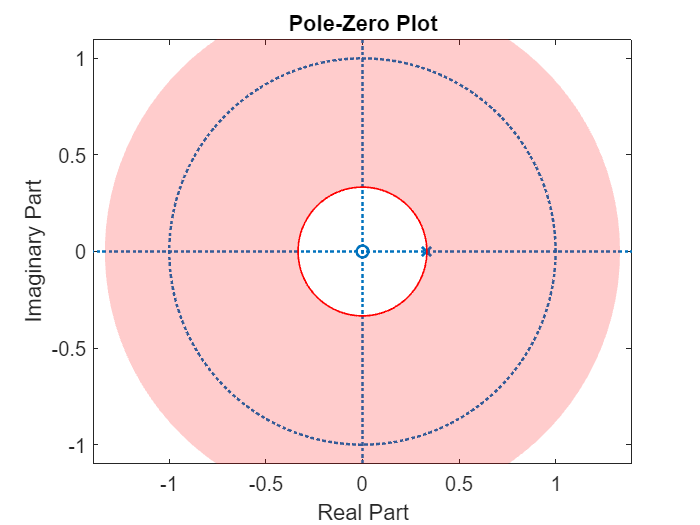

centro = [0, 0]; % [h, k]
radio = abs(polos);
theta = linspace(0, 2*pi, 100); 

% Indicar si el sistema es causal o no
causal = true;   % true = ROC hacia afuera, false = ROC hacia adentro

% Calcular puntos del borde
x = centro(1) + radio * cos(theta);
y = centro(2) + radio * sin(theta);

figure
zplane(ceros, abs(polos));
hold on

plot(x, y, 'r', 'LineWidth', 1);  % borde del círculo

if causal
    % ROC hacia afuera
    r_ext = radio*4; % círculo grande para rellenar exterior
    x_ext = centro(1) + r_ext*cos(theta);
    y_ext = centro(2) + r_ext*sin(theta);

    patch([x_ext fliplr(x)], [y_ext fliplr(y)], ...
          'red','FaceAlpha',0.2,'EdgeColor','none');
else
    % ROC hacia adentro
    patch(x, y, 'red', 'FaceAlpha', 0.2);
end

### Signal 2


$$$x[n] = -[1/2]^n u[-n-1]$$$



clc, clear;

polos = -1/2;
ceros = 0;

[num, den] = zp2tf(ceros, polos, 1)

num =      1     0


den =     1.0000    0.5000


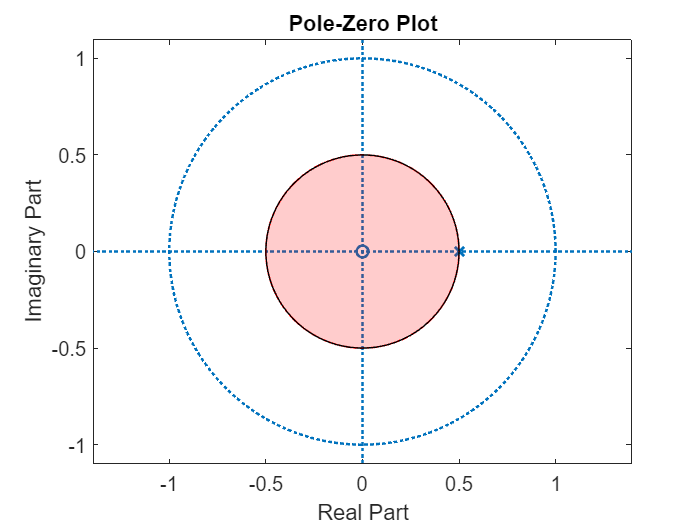

centro = [0, 0]; % [h, k]
radio = abs(polos);
theta = linspace(0, 2*pi, 100); 

% Indicar si el sistema es causal o no
causal = false;   % true = ROC hacia afuera, false = ROC hacia adentro

% Calcular puntos del borde
x = centro(1) + radio * cos(theta);
y = centro(2) + radio * sin(theta);

figure
zplane(ceros, abs(polos));
hold on

plot(x, y, 'r', 'LineWidth', 1);  % borde del círculo

if causal
    % ROC hacia afuera
    r_ext = radio*4; % círculo grande para rellenar exterior
    x_ext = centro(1) + r_ext*cos(theta);
    y_ext = centro(2) + r_ext*sin(theta);

    patch([x_ext fliplr(x)], [y_ext fliplr(y)], ...
          'red','FaceAlpha',0.2,'EdgeColor','none');
else
    % ROC hacia adentro
    patch(x, y, 'red', 'FaceAlpha', 0.2);
end

### Signal 3


$$$x[n] = (1/2)^n u[n] - (2)^n u[-n-1]$$$


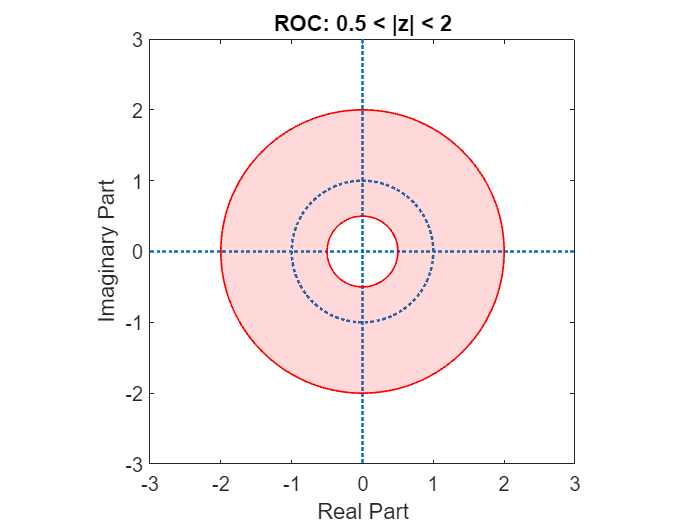

clc; clear; close all;

polos = [0.5 2];
ceros = 0;
k = -3/2;

[num, den] = zp2tf(ceros, polos, k);

figure
zplane(ceros, polos)
hold on
axis equal
xlim([-3 3])
ylim([-3 3])

theta = linspace(0,2*pi,200);

r1 = 0.5;
r2 = 2;

x1 = r1*cos(theta);
y1 = r1*sin(theta);

x2 = r2*cos(theta);
y2 = r2*sin(theta);

% rellenar ROC (corona)
patch([x2 fliplr(x1)], [y2 fliplr(y1)], ...
      'red','FaceAlpha',0.15,'EdgeColor','none');

% dibujar bordes
plot(x1,y1,'r','LineWidth',1)
plot(x2,y2,'r','LineWidth',1)

title('ROC: 0.5 < |z| < 2')

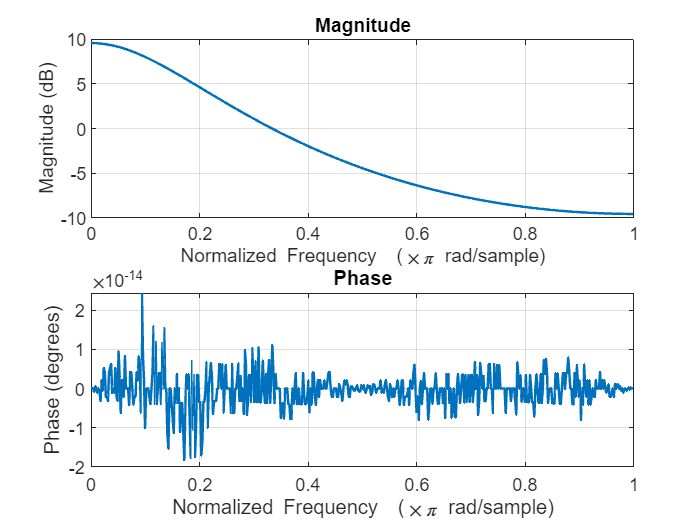


figure
freqz(num, den)

### Signal 4

clc; clear;

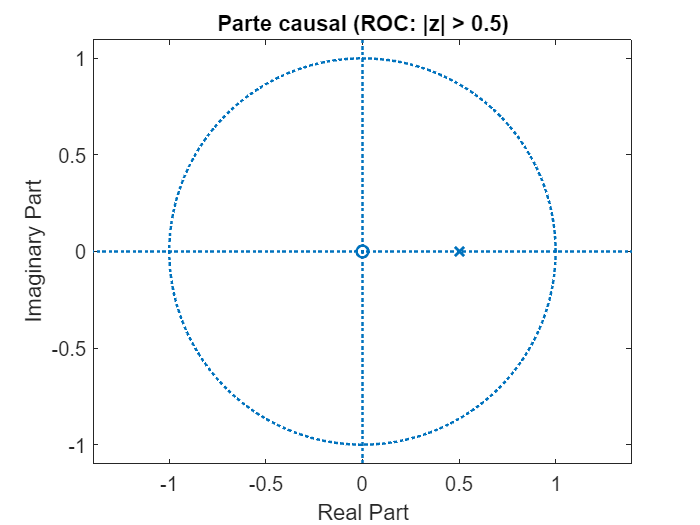

clc; clear; close all;

a = 1/2;

% Parte causal:  -(a^n)u[n]
zeros1 = 0;
poles1 = a;
k1 = -1;               % H1(z) = - z/(z-a)

% Parte anticausal: -(a^n)u[-n-1]
zeros2 = 0;
poles2 = a;
k2 = +1;               % H2(z) = + z/(z-a)  (misma racional, otra ROC)

[num1, den1] = zp2tf(zeros1, poles1, k1);
[num2, den2] = zp2tf(zeros2, poles2, k2);

figure; zplane(zeros1, poles1); title('Parte causal (ROC: |z| > 0.5)');

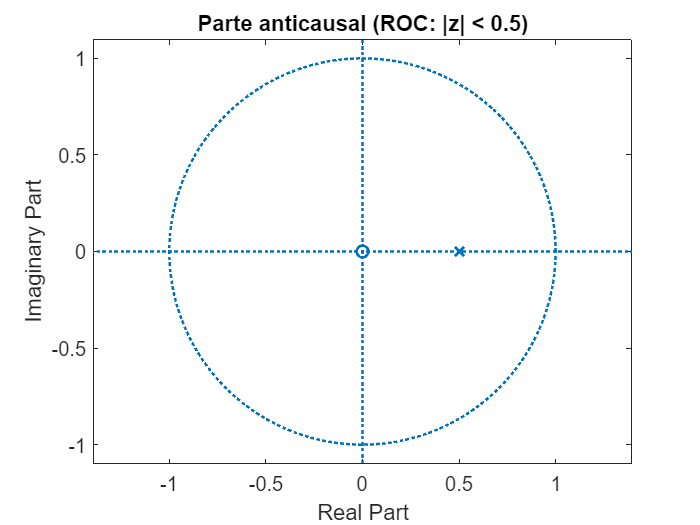

figure; zplane(zeros2, poles2); title('Parte anticausal (ROC: |z| < 0.5)');


% Nota: la señal total NO tiene ROC (intersección vacía)



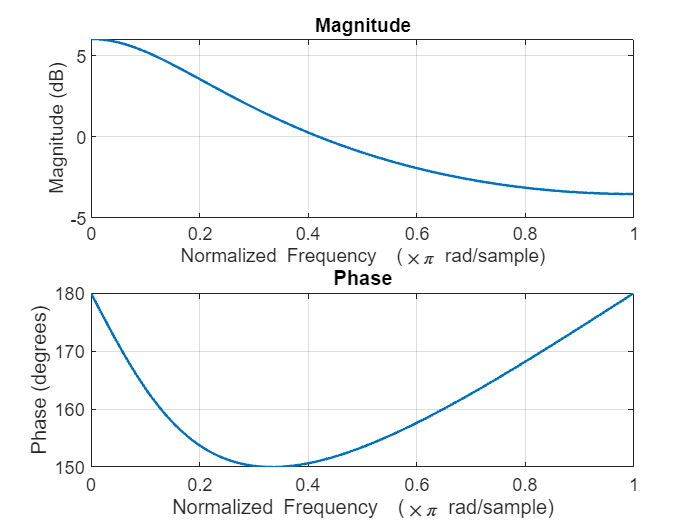

figure
freqz(num1, den1)

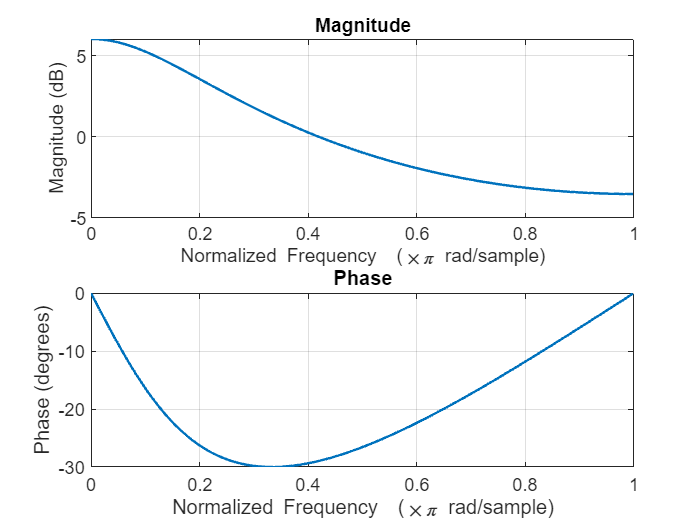

figure
freqz(num2, den2)

## Conclusiones y Preguntas

- En este ejercicio concluimos que 